## Input profile

### Define Input Profile

f_input = [10 1000];
ASD_input = 0.001*[ones(1,2)];
filename = 'output.txt';

### Define Output Profile 

F0 = max(10, f_input(1)); %initial frequency
Fr = 2.5; %interpolation resolution
Fmax = min(1000, f_input(end)); % final frequency

### Interpolate Input Profile

Fs = 2*f_input(end);

f = F0:Fr:Fs/2;
PSD = exp(interp1(log(f_input), log(ASD_input), log(f), 'linear'));

Grms = sqrt(trapz(PSD)*Fr);

### plot Input Profile

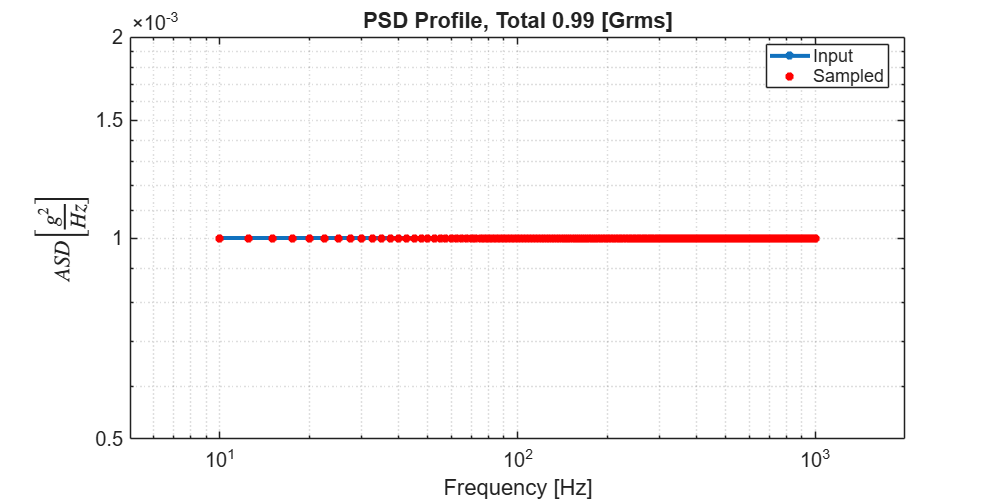

figure('Position',[0 0 1000 500])
loglog(f_input, ASD_input, '-*','LineWidth',3, 'DisplayName',  'Input');
hold on
loglog(f, PSD, 'r*','LineWidth',3, 'DisplayName','Sampled');
grid minor
xlim([0.5*min(f_input) 2*max(f_input)])
ylim([0.5*min(ASD_input) 2*max(ASD_input)])
ylabel('$ASD \left[\frac{g^2}{Hz}\right]$', 'Interpreter','latex')
xlabel('Frequency [Hz]')
title(sprintf('PSD Profile, Total %.2f [Grms]', Grms))
legend('show', 'Location','best')

set(gca, 'fontsize', 15)

## Export for Simulate

dataTable = table(f', PSD');
writetable(dataTable, filename, 'Delimiter', '\t', 'WriteVariableNames',false);